% 用三种方式表示下面的图，Edge List，Adjacency Matrix，Adjacency List。 
% 然后依据给出的一条边的两个顶点（有向图需要区分起点和终点），查找同一张图不同表示法对应的数据结构，确定需要查找的这条边是否存在。
% 可以看到不同的表示方法各有优缺点，有的构造的数据结构比较简单，但搜索慢，有的数据结构比较复杂，但搜索快。

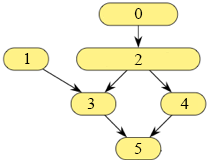

isEdgeExist = findDirectedEdge(2, 4, 'adjList');
disp(isEdgeExist);

The Edge from Vertex 2 to Vertex 4 exists.


function edgeExist = findDirectedEdge(vertexFrom, vertexTo, graphName)

    switch graphName
        
        case "edgeList"
            edgeList = [0, 2; 1, 3; 2, 3; 2, 4; 3, 5; 4, 5];
            numEdge = size(edgeList);
            i = 1;
            while(i <= numEdge(2))
                if (vertexFrom == edgeList(i,1)) & (vertexTo == edgeList(i,2))
                    txtDisp = ['The Edge from Vertex ', num2str(vertexFrom), ' to Vertex ', num2str(vertexTo), ' exists.'];
                    edgeExist = txtDisp;
                    return;
                else
                    i = i + 1;
                end                 
            end
            txtDisp = ['The Edge from Vertex ', num2str(vertexFrom), ' to Vertex ', num2str(vertexTo), ' doesn', '''', 't exist.'];
            edgeExist = txtDisp;            
            
        case "adjMatrix"
                        % 0  1  2  3  4  5 
             adjMatrix = [0, 0, 1, 0, 0, 0;   % 0
                          0, 0, 0, 1, 0, 0;   % 1
                          0, 0, 0, 1, 1, 0;   % 2
                          0, 0, 0, 0, 0, 1;   % 3
                          0, 0, 0, 0, 0, 1;   % 4
                          0, 0, 0, 0, 0, 0];  % 5
            
            if adjMatrix(vertexFrom+1, vertexTo+1) == 1    % 注意 MATLAB 的下标从 1 开始，因此要 +1 来和图对应。
                txtDisp = ['The Edge from Vertex ', num2str(vertexFrom), ' to Vertex ', num2str(vertexTo), ' exists.'];                
            else
                txtDisp = ['The Edge from Vertex ', num2str(vertexFrom), ' to Vertex ', num2str(vertexTo), ' doesn', '''', 't exist.'];
            end          
            edgeExist = txtDisp;
                        
        case "adjList"
            adjList = {[2];
                       [3];
                       [3, 4];
                       [5];
                       [5];
                       [-1]};    % 以 -1 表示不存在由此 Vertex 发出的边。
            i = 1;
            lenRow = length(adjList{vertexFrom+1,:});
            while(i <= lenRow)
                if adjList{vertexFrom+1,1}(i) == vertexTo    % 注意元胞数组的表示方法。
                    txtDisp = ['The Edge from Vertex ', num2str(vertexFrom), ' to Vertex ', num2str(vertexTo), ' exists.'];                
                    edgeExist = txtDisp;
                    return;
                else
                    i = i + 1;
                end
            end          
            txtDisp = ['The Edge from Vertex ', num2str(vertexFrom), ' to Vertex ', num2str(vertexTo), ' doesn', '''', 't exist.'];
            edgeExist = txtDisp;
                           
            otherwise    
                edgeExist = "graphName is wrong!";
            
    end
end